Constants

syms A B gamma real
assumeAlso(A > 0 & B > 0)

State variables

syms X Y Z real
S = [X;Y;Z];

Reaction rates

syms k1 k2 k3 k4 k5 real

State equations

dX = k1*A*Y - k2*X*Y + k3*A*X - 2*k4*X^2;
dY = -k1*A*Y -k2*X*Y + gamma/2*k5*B*Z;
dZ = 2*k3*A*X - k5*B*Z;
f = [dX;dY;dZ];

Transformed state variables and parameters

syms x y z real
s = [x;y;z];
x_expr = 2*k4*X/(k3*A);
y_expr = k2*Y/(k3*A);
z_expr = k5*k4*B*Z/(k3*A)^2;
tau_expr = k5*B*sym('t'); % Time rescaling
epsilon = k5*B/(k3*A);
epsilonPrime = 2*k5*k4*B/(k2*k3*A);
q = 2*k1*k4/(k2*k3);

Transformed state equations

dx = ( q*y - x*y + x*(1 - x) ) / epsilon;
dy = ( -q*y - x*y + gamma*z ) / epsilonPrime;
dz = x - z;
g = [dx;dy;dz];

Numerical values

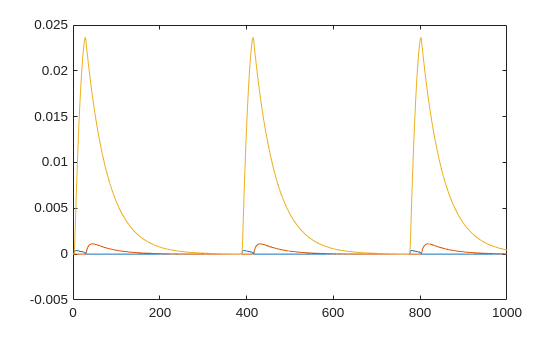

A = 0.06;
B = 0.02;
k1 = 1.28;
k2 = 2.4e6;
k3 = 33.6;
k4 = 2400;
k5 = 1;
gamma = 1;
f_ode = matlabFunction(subs(f),'Vars',{sym('t'),S});

g_ode = matlabFunction(subs(g),'Vars',{sym('t'),s});

S0 = [1;1;1]*1e-6;
[tt,xx] = ode89(f_ode,[0 1000],S0);
plot(tt,xx)

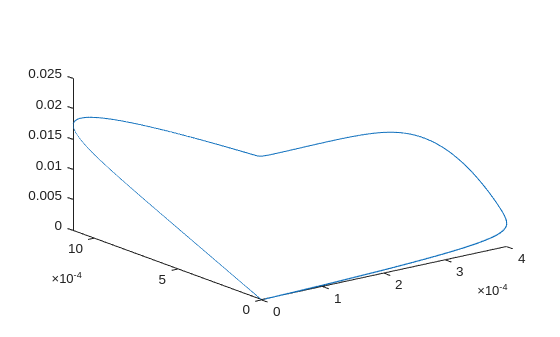

plot3(xx(:,1),xx(:,2),xx(:,3))

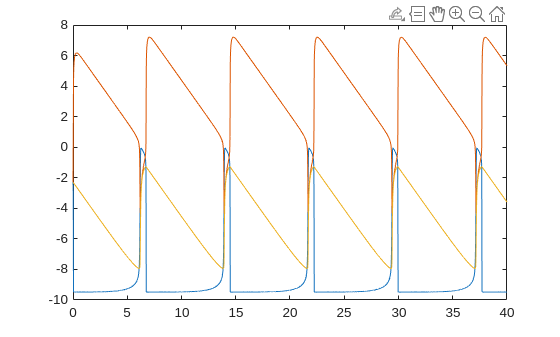

s0 = [1;1;1]/10;
[tt,xx] = ode89(g_ode,[0 40],s0);
xx = log(xx);
plot(tt,xx)

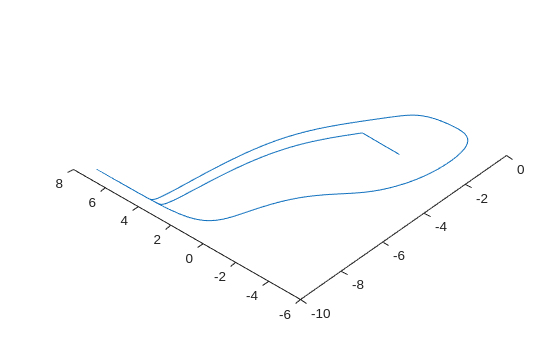

plot3(xx(:,1),xx(:,2),xx(:,3))

sol = solve(subs(f),X,'ReturnConditions',true)
double([sol.X sol.Y sol.Z])